# Lecture 4: Free Vibration - Eigenmodes and Eigenfrequencies

- Find the (undamped) eigenfrequencies $\omega$ and eigenmodes $\vec{u}$ of the system.

- Determine modal mass and stiffness matrices.

- Convert nominal coordinates to modal coordinates and vice-versa.

- Simulate the free response of the unforced system.

Welcome! In this script we're going to analyze the motion of an unforced (i.e., no external forces/moments/prescribed displacements) 2DoF Spring Mass system with the equation of motion: 

$[M_0]\ddot{\vec{q}}+[K_0]\vec{q} = \vec{0}
$.

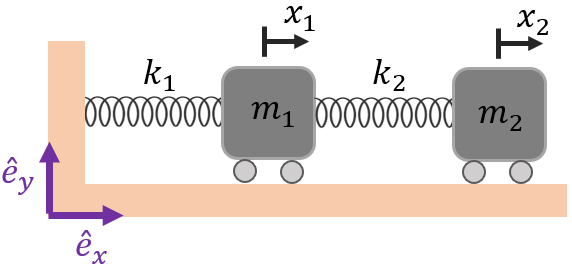

The generalized coordinates are chosen as$\;\vec{\;q} =\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$.

The parameters of the model are:

- $m_1$ = 0.48               [kg]

- $m_2$ = 0.48               [kg]

- $k_1$ = 170                 [N/m]

- $k_2$ = 170                 [N/m]

Using Lagranges Equation of Motion it can be shown that

$\left\lbrack M_0 \right\rbrack =\left\lbrack \begin{array}{cc}
m_1  & 0\\
0 & m_2 
\end{array}\right\rbrack$, $\left\lbrack K_0 \right\rbrack =\left\lbrack \begin{array}{cc}
k_1 +k_2  & -k_{2\;} \\
-k_2  & k_2 
\end{array}\right\rbrack$

## Mass and Stiffness matrices

clc; clear all; close all;

% Parameter values:
m1 = 3.5;                             
m2 = 3.5;
k1 = 335;
k2 = 335;

% Mass and Stiffness matrices can be derived from Lagrange Equation and are given here:
M = [m1, 0;                     % kg (Mass Matrix)
    0, m2];
K = [k1+k2, -k2;                % N/m (Stiffness Matrix)
    -k2,    k2];

## Eigenmodes and eigenfrequencies

To find the (undamped) eigenfrequencies and eigenmodes we set all external forces and damping = 0. Then, we guess a solution in the form $\vec{q}(t) = \vec{u} \cos(\omega t+\phi)$.


$$[M_0]\ddot{q}+[K_0]q = 0
$$



$$-\omega ^2[M_0]\vec{u}\cos(\omega t+\phi)+ [K_0]\vec{u}\cos(\omega t+\phi) = 0$$



$$-\omega ^2 [M_0]\vec{u} + [K_0]\vec{u} = 0$$



$$\underbrace{\omega^2}_{\lambda} \vec{u} =\underbrace{ [M_0]^{-1}[K_0]}_{[A]}\vec{u}$$


This is in the form of the eigenvalue/eigenvector solution $\lambda \vec{u} = [A] \vec{u}$. So that means the eigenfrequencies and eigenmodes are found from `eig(A)`.

[U,lambda] = eig(M\K);         % Solve for eigenmatrix (U) and eigenvalues matrix (lambda)
u1 = U(:,1)                    % 1st eigenmode

u1 =    -0.5257
   -0.8507


u2 = U(:,2)                    % 2nd eigenmode

u2 =    -0.8507
    0.5257



w = sqrt(diag(lambda));       % Solve for eigenfrequencies (rad/s)
w1 = w(1)                     % 1st eigenfrequency

w1 = 6.0465

w2 = w(2)                     % 2nd eigenfrequency

w2 = 15.8298

Applying the principle of superposition to the two solutions: $ \vec{u_1} \cos(\omega_{1}t + \phi_1)$  and  $ \vec{u_2} \cos(\omega_{2}t + \phi_2)$ yields the following equation of motion for free vibration. $A_{1\;} ,A_2 ,\phi_1 ,\phi {\;}_{2\;}$are constants to be determined from initial conditions. 


$$\vec{q(t)} =A_1 \vec{u_1} \cos(\omega_{1}t + \phi_1) + A_2 \vec{u_2} \cos (\omega_{2}t + \phi_2)$$